# IMU Analysis

clear
[timestamps, timedelta, data] = parseDataSet("DataSets/cl_zn_step.csv");

% Extract data columns
ax = data(:, 3); 
ay = data(:, 4); 
az = data(:, 5);
leftspeed = data(:, 9); 
leftvolt = data(:, 10);

% Compute pitch estimate
pitch = rad2deg(atan2(-ax, az));



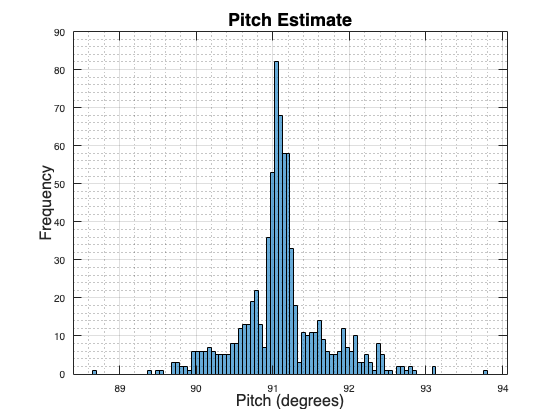


% Create tiled layout
fig = figure;

% Histogram of Pitch Values
histogram(pitch, 100);

title("Pitch Estimate", 'FontSize', 18);
ylabel("Frequency", 'FontSize', 16);
xlabel("Pitch (degrees)", 'FontSize', 16);
grid on; grid minor;

exportgraphics(fig, '../Docs/Y3Report/Images/Graphs/noisyPitchEst.pdf')

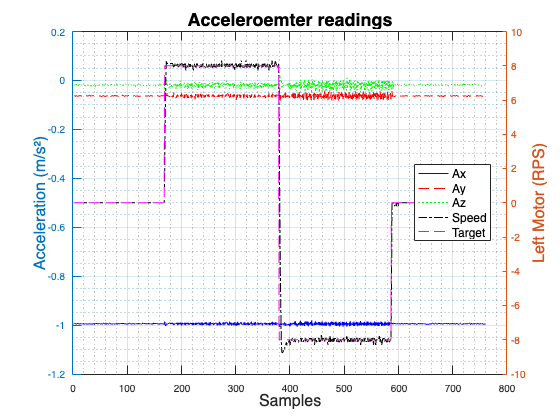

%Accelerometer and Left Motor Data
fig = figure;
yyaxis left;
plot(ax, 'b'); hold on; 
plot(ay, 'r'); 
plot(az, 'g'); 
ylabel('Acceleration (m/s²)', 'FontSize',16);
yyaxis right;
plot(leftspeed, 'k-.'); 
plot(leftvolt, 'm--'); 
ylabel('Left Motor (RPS)','FontSize',16);
title("Acceleroemter readings",  'FontSize', 18);
xlabel("Samples", 'FontSize', 16);
legend("Ax", "Ay", "Az", "Speed", "Target", 'Location', 'best', 'FontSize', 12);
grid on; grid minor;
exportgraphics(fig, '../Docs/Y3Report/Images/Graphs/accelNoiseReadings.pdf')

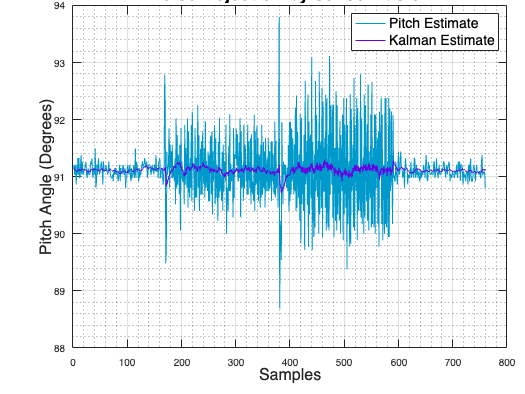

fig = figure;
[timestamps, timedelta, data] = parseDataSet("DataSets/cl_zn_step.csv");
ax = data(:, 3); 
ay = data(:, 4); 
az = data(:, 5);
kal_pitch = data(:,1);

% Compute pitch estimate
pitch_est = rad2deg(atan2(-ax, az));

plot(pitch_est, 'Color', [0.0, 0.6, 0.8, 0.8],'LineWidth', 0.5);hold on;  grid on; grid minor; 
plot(kal_pitch, 'Color', [0.40 ,0.0,0.9], 'LineWidth', 0.2); hold off;
legend("Pitch Estimate", 'Kalman Estimate', 'FontSize', 14); 
title('Noise Rejection by sensor fusion', 'FontSize',18); 
xlabel("Samples",'FontSize',16); 
ylabel('Pitch Angle (Degrees)', 'FontSize',16)
exportgraphics(fig, '../Docs/Y3Report/DesingImgs/SensorFusion.pdf')